# Two-step FAVAR

Tutorial file for testing two-step FAVAR estimators

## Housekeeping

clear
close all
clear classes

rehash path


  
import factorTwostep.*


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");

## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all two-factor FAVAR models, regardless of the specific estimator used.

The properties specific to the two-step FAVAR are as follows:

**reducibleNames** – variables used for constructing the factors. 

**reducibleBlocks** – names of the blocks, indicating which block each reducible belongs to. Note that even if you have only one block, it must still be specified.Note that if you select the `"slowfast"` method in `blockType`, the group names must be `"slow"` and `"fast"`.

**blockType** – specifies which type of estimation method to use. Possible values are:

- `"blocks"` – default value, also used when there is only one block,

- `"slowfast"` – used for the slow–fast method.

**numFactors** – defines how many factors to use for a given block.

estimStart = datex.m(1960,3);
estimEnd = datex.m(2001,8);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["FYFF"],...
    exogenous=[],...
    order=13, ...
    intercept=false, ...
    estimationSpan=estimSpan, ...
    reducibleNames=["IPP" , "IPF" , "IPC" , "IPCD" , "IPCN" , "IPE" , "IPI" , "IPM" , "IPMD" , "IPMND" ,...
        "IPMFG" , "IPD" , "IPN" , "IPMIN" , "IPUT" , "IP" , "IPXMCA" , "PMI" , "PMP" , "GMPYQ" , "GMYXPQ" , ...
        "LHEL" , "LHELX" , "LHEM" , "LHNAG" , "LHUR" , "LHU680" , "LHU5" , "LHU14" , "LHU15" , "LHU26" ,...
        "LPNAG" , "LP" , "LPGD" , "LPMI" , "LPCC" , "LPEM" , "LPED" , "LPEN" , "LPSP" , "LPTU" , "LPT" ,...
        "LPFR" , "LPS" , "LPGOV" , "LPHRM" , "LPMOSA" , "PMEMP" , "GMCQ" , "GMCDQ" , "GMCNQ" , "GMCSQ" ,...
        "GMCANQ" , "HSFR" , "HSNE" , "HSMW" , "HSSOU" , "HSWST" , "HSBR" , "HMOB" , "PMNV" , "PMNO" , ...
        "PMDEL" , "MOCMQ" , "MSONDQ" , "FSNCOM" , "FSPCOM" , "FSPIN" , "FSPCAP" , "FSPUT" , "FSDXP" , ...
        "FSPXE" , "EXRSW" , "EXRJAN" , "EXRUK" , "EXRCAN" , "FYGM3" , "FYGM6" , "FYGT1" , "FYGT5" , ...
        "FYGT10" , "FYAAAC" , "FYBAAC" , "SFYGM3" , "SFYGM6" , "SFYGT1" , "SFYGT5" , "SFYGT10" , ...
        "SFYAAAC" , "SFYBAAC" , "FM1" , "FM2" , "FM3" , "FM2DQ" , "FMFBA" , "FMRRA" , "FMRNBA" , ...
        "FCLNQ" , "FCLBMC" , "CCINRV" , "PMCP" , "PWFSA" , "PWFCSA" , "PWIMSA" , "PWCMSA" , "PSM99Q" , ...
        "PUNEW" , "PU83" , "PU84" , "PU85" , "PUC" , "PUCD" , "PUS" , "PUXF" , "PUXHS" , "PUXM" , "LEHCC" , "LEHM" , "HHSNTN"], ...
    reducibleBlocks=["main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", ...
        "main", "main", "main", "main", "main", "main", "main", "main", "main", "main", "main"],...
    blockType = "blocks", ...    
    numFactors = struct("main",2), ...
    identificationHorizon=12);

## Specifying and loading input data


inputTbx = tablex.fromFile("FAVAR.csv");
dataH = DataHolder(meta, inputTbx);

## Reduced form models

The estimator-specific settings are always the same as those for the corresponding plain BVARs.

### Basic FAVARs

#### **Minnesota priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **diag** – uses only the diagonal elements of the covariance matrix from an estimated VAR (with the same order as the final model),

- **full** – uses the full covariance matrix from an estimated VAR (with the same order as the final model).

estimatorR1 = estimator.MinnesotaFAVARTwostep()

estimatorR1 =   MinnesotaFAVARTwostep with properties:

                Settings: [1×1 factorTwostep.estimator.settings.MinnesotaFAVARTwostep]
             Description: "Two-step FAVAR with Minnesota prior"
                Category: "Two-step plain FAVAR estimators"
           HasCrossUnits: 0
         CanBeIdentified: 1
          OneStepFactors: 0
                   FAVAR: []
          CanHaveDummies: 0
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
          ShortClassName: 'MinnesotaFAVARTwostep'
         BeenInitialized: 0


#### **Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx


% estimatorR1 = estimator.NormalWishartFAVARTwostep()


#### **Normal Diffuse priors**

There are no estimator-specific settings other than the hyperparameters.


% estimatorR1 = estimator.NormalDiffuseFAVARTwostep()


#### **Individual Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx


% estimatorR1 = estimator.IndNormalWishartFAVARTwostep()


#### **Flat priors**

There are no estimator-specific settings other than the hyperparameters.


% estimatorR1 = estimator.FlatFAVARTwostep()


### Stochastic volatility (SV) FAVARs

All SV models (including the general time varying model) share the same estimator specific setings

**HeteroskedasticityAutoRegression **– prior on the autoregression in heteroskedasticity (gamma in BEAR5)

**HeteroskedasticityShape **– prior on the shape of the inverse gamma distribution of the variance of the residual in heteroskedasticity (alpha in BEAR5)

**HeteroskedasticityScale **– prior on the scale of the inverse gamma distribution of the variance of the residual in heteroskedasticity (delta in BEAR5)

#### Standard SV model ( Cogley and Sargent (2005) )

% estimatorR1 = estimator.CogleySargentSVFAVAR()

#### SV model with Random Inertia 

**HeteroskedasticityAutoRegressionVariance **– prior on the variance of the autoregression in heteroskedasticity (zeta0 in BEAR5)

% estimatorR1 = estimator.RandomInertiaSVFAVAR()

#### SV model for large Bayesian VAR ( Carriero et al. (2012) )

% estimatorR1 = estimator.CogleySargentSVFAVAR()

### Time-varying FAVARs

#### **Time varying dynamic parameters only**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.BetaTVFAVAR()

#### **Time varying dynamic parameters and stochastic volatility**

As mentioned above the common SV setings could be applied here as well

% estimatorR1 = estimator.GeneralTVFAVAR()

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVARTwostep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.6023
   -0.0482
   -0.0279
    0.0477
   -0.0071
    0.0079
    0.0857
   -0.0144
   -0.0059
    0.0406


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2000-10


fcastEnd = datetime
   2001-08



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

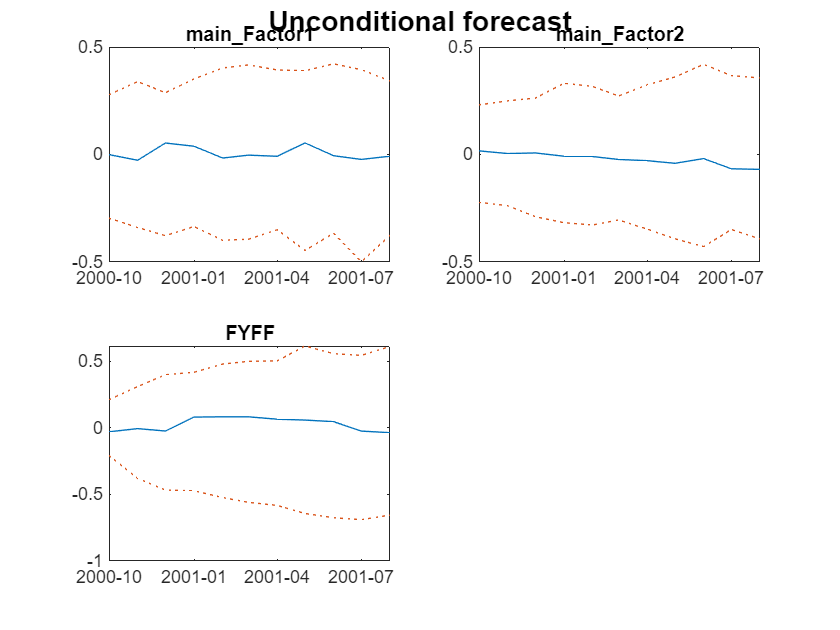


plotSettings = { ...
    {"color"}, {defaultColors(2,:); defaultColors(1,:); defaultColors(2,:)},  ...
    {"lineStyle"}, {":";"-";":"}, ...
};


ch = visual.Chartpack( ...
    span=datex.span(fcastStart, fcastEnd), ...
    namesToPlot=[modelR1.Meta.PseudoEndogenousNames], ...
    plotSettings=plotSettings ...
);

ch.Captions = "Unconditional forecast";
ch.plot(fcastPrctileTbx);

## Identification

### Cholesky

#### Seting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();


info1 = modelS1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVARTwostep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [117×1 double]
                 sigma: [3×3 double]
                    FY: [511×3 double]
                    LD: [120×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.5966    0.0560    0.0937
    0.0225    0.7415    0.0891
   -0.1411    0.0424    1.0978
    0.1439    0.0190    0.0078
    0.0042    0.0543    0.0153
    0.0412   -0.0244   -0.1559
    0.0550    0.0161   -0.0020
   -0.0470    0.0380    0.0356
    0.0223   -0.0080   -0.0668
   -0.0148   -0.0065   -0.0063


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.5966    0.0560    0.0937
    0.0225    0.7415    0.0891
   -0.1411    0.0424    1.0978
    0.1439    0.0190    0.0078
    0.0042    0.0543    0.0153
    0.0412   -0.0244   -0.1559
    0.0550    0.0161   -0.0020
   -0.0470    0.0380    0.0356
    0.0223   -0.0080   -0.0668
   -0.0148   -0.0065   -0.0063


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =     0.2227         0         0
         0    0.1650         0
         0         0    0.1661


modelS1.Presampled{2}.D

ans =     0.2227         0         0
         0    0.1650         0
         0         0    0.1661


## Impulse respones (IRF)

### Plot settings

plotStart = datex.shift(modelS1.Meta.EstimationEnd, 1); 
plotEnd = datex.shift(modelS1.Meta.EstimationEnd, modelS1.Meta.IdentificationHorizon);
plotSpan = datex.span(plotStart, plotEnd);

### Cholesky

respTbl1 = modelS1.simulateResponses();


  (MinnesotaFAVARTwostep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.apply(respTbl1, prctileFunc);
respTbl1 = tablex.flatten(respTbl1);

respTbl1

respTbl1 = 25×9 timetable
     Time      main_Factor1___main_Factor1_shock      main_Factor1___main_Factor2_shock            main_Factor1___FYFF_shock           main_Factor2___main_Factor1_shock     main_Factor2___main_Factor2_shock       main_Factor2___FYFF_shock           FYFF___main_Factor1_shock          FYFF___main_Factor2_shock              FYFF___FYFF_shock      
    _______    _________________________________    _____________________________________    _____________________________________    ___________________________________    _________________________________    ________________________________    _______________________________    ________________________________

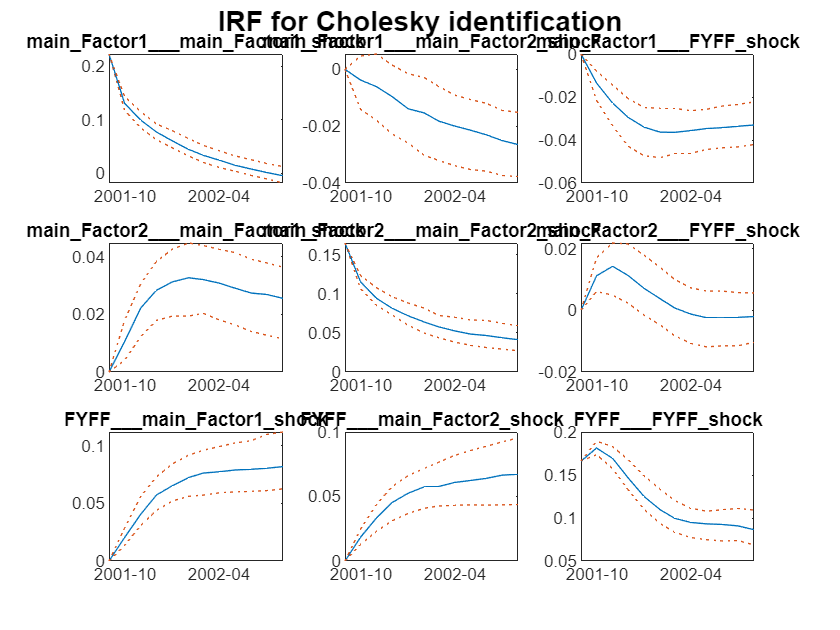


ch = visual.Chartpack( ...
  span=plotSpan, ...
  namesToPlot=string(respTbl1.Properties.VariableNames), ...
  plotSettings=plotSettings ...
);

ch.Captions = "IRF for Cholesky identification";
ch.plot(respTbl1);

## **Unconditional forecast shock decomposition**


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

tablex.getHigherDims(uncFcastContribTbl1)

ans = 1×1 cell array
    {["main_Factor1_shock"    "main_Factor2_shock"    "FYFF_shock"    "Exogenous"    "Initials"]}


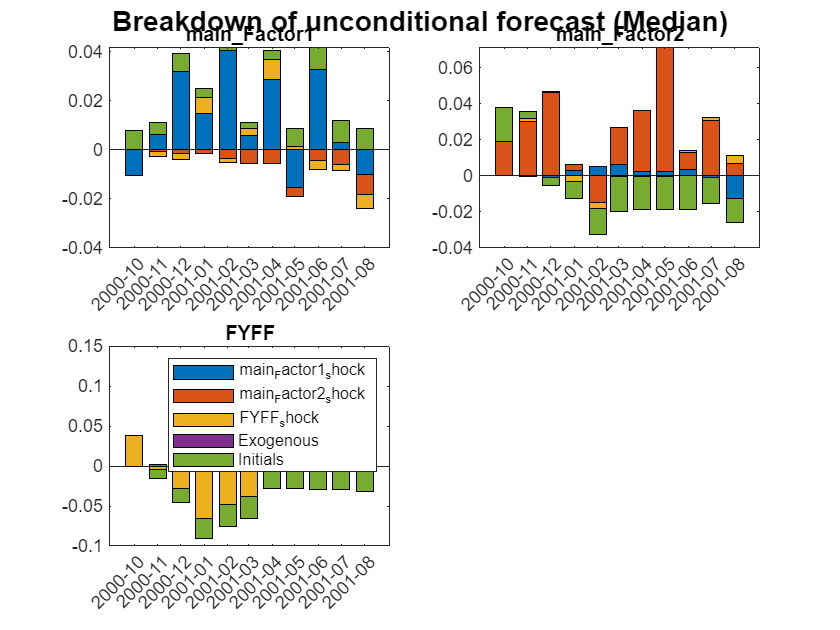


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);
contMedTbx = tablex.apply(contMedTbx, flatFunc);

ch = visual.Chartpack( ...
    span=fcastSpan, ...
    namesToPlot=modelS1.Meta.PseudoEndogenousNames, ...
    captions="Breakdown of unconditional forecast (Median)", ...
    plotFunc=@bar ...
);
ch.plot(contMedTbx);
leg = tablex.getHigherDims(contMedTbx);
legend(leg{1});

## **FEVD**


fevdTbx = modelS1.calculateFEVD();


  (MinnesotaFAVARTwostep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




tablex.getHigherDims(fevdTbx)

ans = 1×1 cell array
    {["main_Factor1_shock"    "main_Factor2_shock"    "FYFF_shock"]}


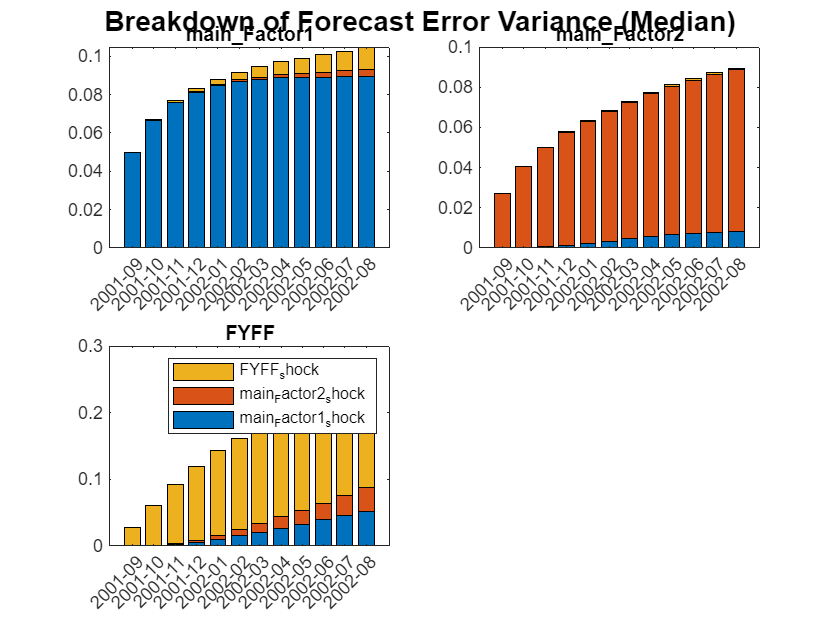


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);
fevdMedTbx = tablex.apply(fevdMedTbx, flatFunc);

ch = visual.Chartpack( ...
    span=plotSpan, ...
    namesToPlot=modelS1.Meta.PseudoEndogenousNames, ...
    captions="Breakdown of Forecast Error Variance (Median)", ...
    plotFunc=@bar ...
);
ch.plot(fevdMedTbx);
leg = tablex.getHigherDims(fevdMedTbx);
legend(leg{1});

## Conditional forecast

### Settig up the conditions and the forecast plan

condDataTbl = tablex.fromFile("condDataTblFAVAR.xlsx");
planTbl = tablex.readConditioningPlan("planTblFAVAR.xlsx");

### Settig up the forecast range 

cfcastSpan = fcastSpan;

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 





condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 





condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

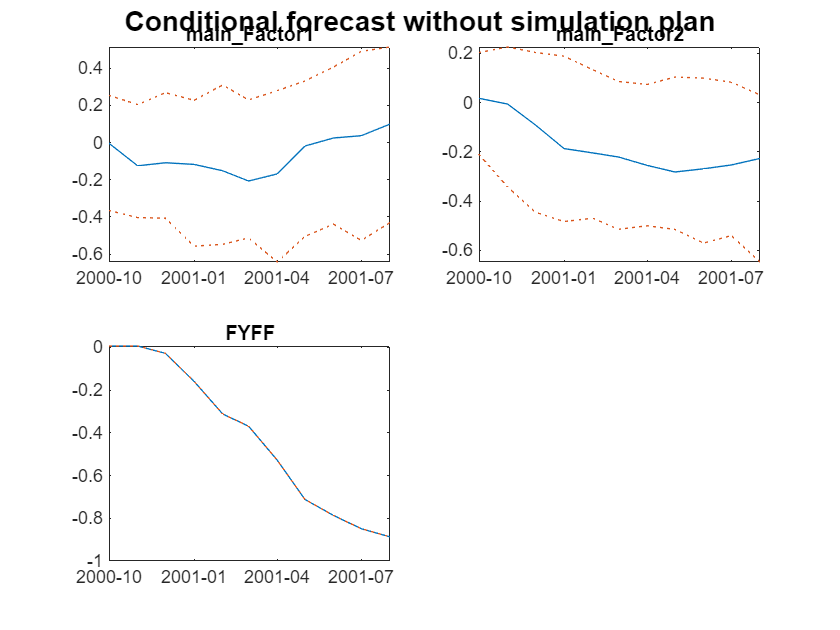

ch = visual.Chartpack( ...
  span=cfcastSpan, ...
  namesToPlot=[modelS1.Meta.PseudoEndogenousNames], ...
  plotSettings=plotSettings ...
);

ch.Captions = "Conditional forecast without simulation plan";
ch.plot(condFcastPrctilesTbl1);

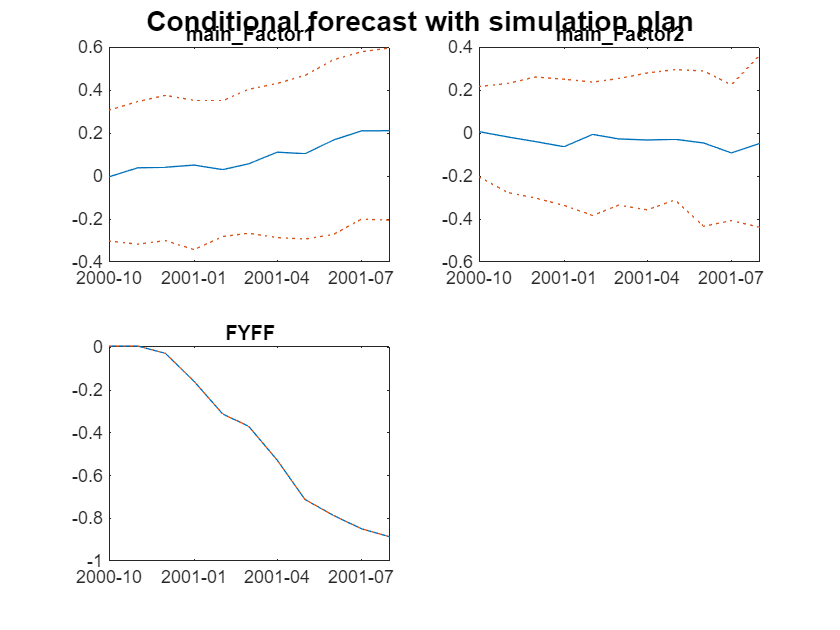


ch.Captions = "Conditional forecast with simulation plan";
ch.plot(condFcastPrctilesTbl2);